# Lesson I.6:   Vectors and Matrices (F24)

Matrices are rectangular arrays of numbers.    The set of all such arrays of real numbers having $m$ row and $n$ columns is denoted as ${\mathbb R}^{m\times n}
$; for the set of rectangular arrays of complex numbers with the same number of rows and column the designation is ${\mathbb C}^{m\times n}$.    Column vectors can the thought of as a matrix having only one column.   Thus, ${\mathbb R}^{n\times 1}$ is essentially the same set as ${\mathbb R}^n$, and ${\mathbb C}^{n\times 1}$, the same as ${\mathbb C}^n$.   

**Linear combinations.**    The most basic operation on matrices, as for vectors, is the *formation of linear combinations*.   The formation of linear combinations is a composite of scalar multiplication and matrix addition.    For the concrete vectors and matrices considered in this course, scalar multiplication consists of multiplying each element of the array by a given scalar,

        (I.6.1a)                           $\alpha\quad \left[\matrix{
A_{11} &A_{12}&\cdots&A_{1n}\cr
A_{21}& A_{22}& & A_{2n}\cr
\vdots &  & \ddots & \vdots \cr
A_{m1} & A_{m2&\cdots & A_{mn} \cr
}\right]~=~
\left[\matrix{\alpha
A_{11} &\alpha A_{12}&\cdots&\alpha A_{1n}\cr
\alpha A_{21}&\alpha A_{22}& &\alpha A_{2n}\cr
\vdots &  & \ddots & \vdots \cr
\alpha A_{m1} &\alpha A_{m2&\cdots &\alpha A_{mn} \cr
}\right]$

and matrix addition consists of adding corresponding components,

        (I.6.1b)              $ \left[\matrix{
A_{11} &A_{12}&\cdots&A_{1n}\cr
A_{21}& A_{22}& & A_{2n}\cr
\vdots &  & \ddots & \vdots \cr
A_{m1} & A_{m2&\cdots & A_{mn} \cr
}\right]~+~ \left[\matrix{
B_{11} &B_{12}&\cdots&B_{1n}\cr
B_{21}& B_{22}& & B_{2n}\cr
\vdots &  & \ddots & \vdots \cr
B_{m1} & B_{m2&\cdots & B_{mn} \cr
}\right]~=~
 \left[\matrix{
A_{11}+B_{11} &A_{12}+B_{12}&\cdots&A_{1n}+B_{1n}\cr
A_{21}+B_{12}& A_{22}+B_{22}& & A_{2n}+B_{2n}\cr
\vdots &  & \ddots & \vdots \cr
A_{m1}+B_{m1} & A_{m2}+B_{m2}&\cdots & A_{mn}+B_{mn} \cr
}\right]$.

Hence, a linear combinations of matrices is a matrix where each entry is an appropriate linear combination:

        (1.6.1c)     $\alpha\quad \left[\matrix{
A_{11} &A_{12}&\cdots&A_{1n}\cr
A_{21}& A_{22}& & A_{2n}\cr
\vdots &  & \ddots & \vdots \cr
A_{m1} & A_{m2|&\cdots & A_{mn} \cr
}\right]~+~
\beta \quad \left[\matrix{
B_{11} &B_{12}&\cdots&B_{1n}\cr
B_{21}& B_{22}& & B_{2n}\cr
\vdots &  & \ddots & \vdots \cr
B_{m1} &B_{m2}&\cdots & B_{mn} \cr
}\right]~=~
\left[\matrix{\alpha
A_{11} +\beta B_{11} &\alpha A_{12} +\beta B_{12} &\cdots&\alpha A_{1n} +\beta B_{1n} \cr
\alpha A_{21} +\beta B_{21} &\alpha A_{22} +\beta B_{22} & &\alpha A_{2n} +\beta B_{2n} \cr
\vdots &  & \ddots & \vdots \cr
\alpha A_{m1} +\beta B_{m1}  &\alpha A_{m2} +\beta B_{m2} &\cdots &\alpha A_{mn} +\beta B_{mn}  \cr
}\right]$.

The formation of linear combinations, a modest generalization of linear combinations of column vectors, is a simple but essential concept which importantly extends to more abstract conceptions of vectors such as functions.  

            $f(x)~=~3\sin x ~+~\frac{22}{7}e^x~+~\pi (x^3-x+1)^5$     is a linear combination of $\sin x$, $e^x$ and $(x^3-x+1)^5$.     

**Matrix-vector multiplication.**   Matrix-vector multiplication is defined as a particular linear combination.    Let $A=\left[ \matrix{{\bf a_1} & {\bf a_2}&\cdots &{\bf  a}_n}\right]$ be an $m\times n$ matrix with columns ${\bf a_1},~{\bf a_2},\cdots,{~\bf a}_n$ each in ${\mathbb R}^m$, and let ${\bf x}$ be a vector in ${\mathbb R}^m$ with components $x_1,~x_2,\dots,~x_m$.   The matrix product $A{\bf x}$ is the linear combination of the columns of $A$ with coefficients $x_1,~x_2,\dots,~x_m$:

        (I.6.2)              $A{\bf x}~=~\left[\matrix{{\bf a}_1 & {\bf a}_2 & \cdots & {\bf a}_n}\right] \left[\matrix{x_1\cr x_2\cr \vdots \cr x_n}\right]~=
~x_1{\bf a_1}~+~ x_2{\bf a_2}~+~\cdots~+~x_n {\bf a_n}$.

For example

            $\left[\matrix{
1&4&7&10\cr
2&5&8&11\cr
3&6&9&12\cr}\right]
\left[\matrix{1\cr-1\cr3\cr-2}\right]~=~
1\left[\matrix{1\cr2\cr3\cr}\right]~+~(-1)\left[\matrix{4\cr5\cr 6}\right]~+~3\left[\matrix{7\cr 8\cr 9}\right]~+~(-2)\left[\matrix{10\cr11\cr12}\right]~=~
\left[\matrix{1\cr2\cr3}\right]~+~\left[\matrix{-4\cr-5\cr -6}\right]~+~\left[\matrix{21\cr24\cr27}\right]~-~\left[\matrix{20\cr 22\cr 24}\right]~=~\left[\matrix{-2\cr-1\cr0}\right]$.

MATLAB is proficient at matrix-vector multiplication:

A=[1 4 7 10; 2 5 8 11; 3 6 9 12];
x=[1;-1;3;-2];
A*x

ans =     -2
    -1
     0


A key algebraic property of matrix-vector multiplication concerns multiplying a matrix times a linear combination of vectors:

        (I.6.3a)                $A(\alpha{\bf x}+\beta{\bf y})~=~\alpha A {\bf x} ~+~\beta A{\bf y}$.

An important interpretation of this identity is that the formation of linear combinations commutes with multiplication by a matrix.   That is, suppose one is given a matrix $A\in{\mathbb R}^{m\times n}$, a set of vectors $\{{\bf x_1},{\bf x_2},\dots,{\bf x_p}\}\subset{\mathbb R^n$ and a set of coefficients $\{\alpha_1,\alpha_2,\dots,\alpha_p\}$.   Then the following two different processes always give the same result:

- Use the given vectors and coefficients to form a linear combination ($\alpha_1{\bf x_1}+\alpha_2{\bf x_2}+\cdots+\alpha_p{\bf x}_p$) and then multiple by the matrix $A$ to obtain ${\bf r}_1=A(\alpha_1{\bf x_1}+\alpha_2{\bf x_2}+\cdots+\alpha_p{\bf x}_p)$.

- Multiply each of the given vectors by $A$ to get a new set of vectors $\{A{\bf x}_1,A{\bf x}_2,\dots,A{\bf x}_p\}$ and then use the given coefficients with this new set to form a linear combination ${\bf r}_2=\alpha_1A{\bf x}_1+\alpha_2A{\bf x}_2+\cdots+\alpha_pA{\bf x}_p$.

The property (I.6.3a) implies ${\bf r}_1~=~{\bf r}_2$.

Linear combinations within the first factor of a matrix-vector product work similarly:

        (I.6.3b)              $(\alpha A +\beta B){\bf x}~=~ \alpha A {\bf x}~+~\beta B{\bf x}$.

**Application to writing linear systems.**  A moment's reflection reveals that the linear system having a coefficient matrix $A$ and a RHS ${\bf b}$ (hence an augmented matrix $\left[\matrix{~A &|& {\bf b}~}\right]$) can also be written in terms of matrix-vector multiplication as

        (I.6.4)                $A{\bf x}~=~{\bf b}$.

For many applications, this is the most common way of writing linear systems.    

**Linear transformations.   **A given matrix $A$ is a rectangular array of numbers, but it is generally more useful to think about what a matrix does "does" than what it "is."     Specifically, the $m\times n$ matrix $A$ can be through of defining a linear function $T\;$taking a vector ${\bf x}\in {\mathbb R}^n$ and transforming it into a vector ${\bf y}=T({\bf x})=A{\bf x}\in{\mathbb R}^m$.   The source of input vectors for the function ${\mathbb R}^n$ is the ***domain*** of the function, and the set where the output vector is found ${\mathbb R}^m$ is the ***codomain***.    The relationship between vectors in the domain and the codomain defined by $T({\bf x})=A{\bf x}$, is a ***linear function ***(also known as a ***linear transformation ***or a ***linear map***) as the function $T$ satisfies

        (I.6.5)               $T(\alpha {\bf x}+\beta{\bf y})~=~ \alpha T({\bf x})~+~\beta T({\bf y})$.

The reader might be tempted to gloss over the notion of linear transformation as an arcane mathematical definition (cf. "homomorphisms on a vector space").    It should be noted, however, that the core object of differential calculus, the derivative, is the (local) approximation of a function by a linear transformation.    Moreover, linear functions defined by matrices, such as the stress and strain tensors of elasticity, are ubiquitous in applications.   Linearity is a key concept both from applied and theoretical perspectives.   Here we see that matrices define linear transformations; later we will see that every linear transformation between spaces of column vectors has a matrix defining it.

**Matrix-matrix multiplication.   **From matrix-vector multiplication where the second factor is restricted to having a single column, we define matrix-matrix multiplication where the second factor may have an unlimited number of columns:    If $A$ is an $m\times n$ matrix and $B$ is an $n\times p$ matrix (i.e. a matrix with $p$ columns each having $n$ components) then the product $\textrm{AB}$ is defined to be the $m\times p$ matrix where the $\ell^\text{th}$ column is matrix-vector product of $A$ times the $\ell^\text{th}$ column of $B$:

        (I.6.6)         $AB=A\left[\matrix{{\bf b}_1 & {\bf b}_2 &\cdots &{\bf b}_p}\right]~=~
\left[\matrix{A{\bf b}_1 &A {\bf b}_2 &\cdots &A{\bf b}_p}\right]$.

A numerical example:


$$\left[\matrix{1&2&3\cr4&5&6\cr 7&8&9}\right]
\left[\matrix{-1 &1&\frac13\cr 2&-2&\frac13 \cr 0& 1 & \frac13}\right]~=~
\left[ \matrix{\quad&
\left[\matrix{1&2&3\cr 4 & 5 & 6\cr 7&8&9}\right]\left[\matrix{-1\cr2\cr0}\right] &\quad &
\left[\matrix{1&2&3\cr 4 & 5 & 6\cr 7&8&9}\right] \left[\matrix{1\cr-2\cr1}\right] &\quad &
\left[\matrix{1&2&3\cr 4 & 5 & 6\cr 7&8&9}\right] \left[\matrix{\frac13\cr\frac13\cr\frac13}\right] &\quad
}\right]~$$


                                        
$$=~
\left[ \matrix{
\quad&
\left[\matrix{3\cr6\cr9}\right]
&\quad&
 \left[\matrix{0\cr0\cr0}\right]
&\quad&\left[\matrix{2\cr5\cr8}\right]
&\quad}\right]~=~\left[\matrix{3&0&2\cr6&0&5\cr 9&0&8}\right]$$


MATLAB can be helpful with numerical matrix-matrix multiplication:

[1 2 3; 4 5 6; 7 8 9]*[-1 1 1/3; 2 -2 1/3; 0 1 1/3]

ans =      3     0     2
     6     0     5
     9     0     8


Matrix-matrix multiplication is directly related to the composition of linear functions.    Specifically, if 

                
$$T_A:  {\mathbb R}^n\to {\mathbb R}^m ~\text{is given by}~T_A({\bf x})=A{\bf x}~\text{with}~A\in{\mathbb R}^{m\times n}$$
 

and

                
$$T_B:  {\mathbb R}^m\to {\mathbb R}^p ~\text{is given by}~T_B({\bf x})=B{\bf x}~\text{with}~B\in{\mathbb R}^{p\times m}$$


then

                $T_B\circ T_A({\bf x})~=~T_B\big(T_A({\bf x})\big)~=~ BA{\bf x}~=~T_{BA}({\bf x})\quad\text{with}\quad BA\in{\mathbb R}^{p\times n}
$.

That is, matrix-matrix multiplication is an algebraic perspective on the function-theoretic concept of composition of linear functions.

**Important perspectives on matrix-matrix multiplication.**   Notice that the matrix-matrix product  $\textrm{AB}$ is defined only if the number of columns of the first factor $B$ equals the number of rows of the second factor $A$.

        (I.6.7)                $\matrix{
A & B &=& C\cr
m\times n & n\times p & & m\times p
}$

This follows from the definition of matrix multiplication since forming linear combinations requires a equal number of vectors and coefficients.    From the function-theoretic perspective, the input of the second function applied $T_A$ must obviously be in the same set as the output of the first function applied $T_B$.

MATLAB will generate an error if we attempt to multiply mismatched matrices:

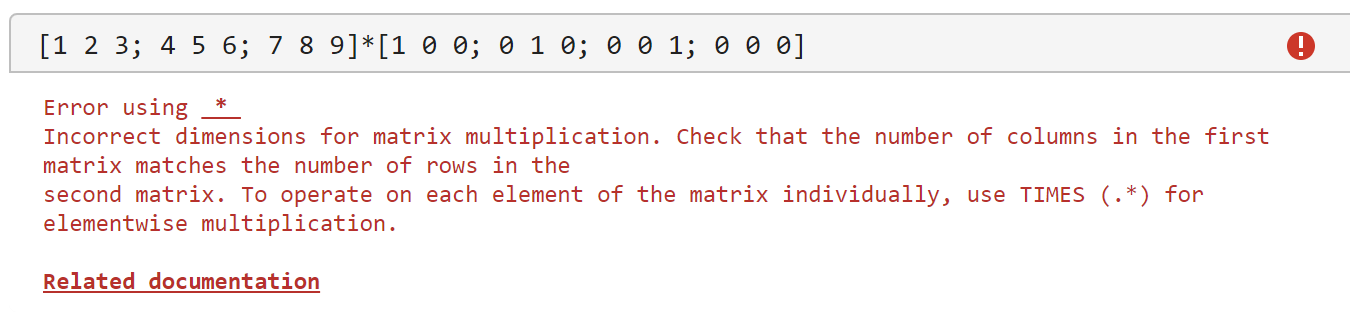

Note:   The code above is not run in this file to avoid creating an error condition.   Rather a screen image of it being run elsewhere is what is presented here.

The entries of the product $C=\textrm{BA}$ have a simple formula.     

         (I.6.8)              $C_{ij}=\sum_{\ell=1}^n B_{i\ell} A_{\ell j}$

Note that the sum is over the index $\ell$ which appears exactly twice in the summand.   (There is a shorthand notation called the *Einstein summation convention* commonly used in fields such as fluid dynamics and elasticity that omits the summation sign but implicitly sums over any repeated index.)

Equation (I.6.8) shows that the entry in the $i^{\text{th}}$ row and the $j^\text{th}$column of the product is the result of combining the entire $i^{\text{th}}$ row of the first factor with the entire $j^\text{th}$column of the second factor.   This is sometimes represented visually by placing the first factor to the left of the product and the second factor above the product.

        (I.6.9)                            $\matrix{ \quad &
\left[
\matrix{\quad
 &\quad & A_{1j} &\quad &\quad&\quad & \quad \cr
 & & A_{2j} & &\cr
 & & \vdots &\cr
 & & A_{mj} & &\cr
}
\right] \cr
\left[ 
\matrix{\quad \cr \quad\cr
B_{i1} & B_{i2} & \cdots & B_{im} \cr \quad 
} \right] &
\left[\matrix{\quad
\cr\quad
\cr
\quad & \quad & C_{ij} & \quad & \quad &\quad &\quad \cr \quad
\cr} \right]}$

This visual display also illustrates that the number of rows in the product matches the number of row of the first factor and the number of columns in the product matches the number of columns of the second factor.

**Non-commutativity of matrix multiplication.   **Supposing that $A$ and $B$ are matrices for which the product $\textrm{AB}$ is defined there are a number of possibilities for the product $\textrm{BA}$:

**Case (1)**: The product $\textrm{BA}$ may be undefined due to the number of columns of $B$ not matching the number of columns of $A$.

A=[1 2 3; 4 5 6];            % 2x3 matrix
B=[0 1 0; 1 0 0; 0 2 3];     % 3x3 matrix
A*B                          

ans =      2     7     9
     5    16    18


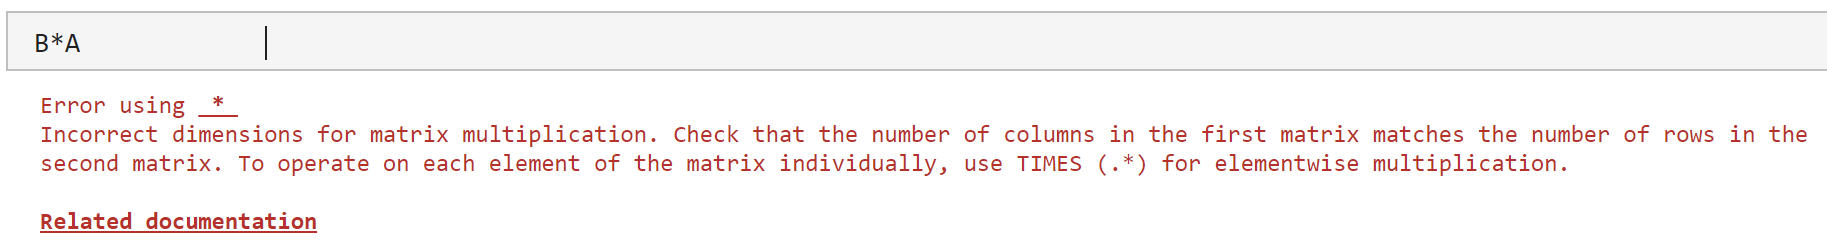

**Case (2)**:  The product $\textrm{BA}$ may be defined but have different dimensions than $\textrm{AB}$.   For example, if $A$ is $3\times 2$ and $B$ $2\times 3$ then $\textrm{AB}$ is $3\times 3$ but $BA$is $2\times 2$.

A=[1 2;4 5; 7 8];           % 3x2
B=[1 2 3; 4 5 6];           % 2x3
A*B

ans =      9    12    15
    24    33    42
    39    54    69


B*A

ans =     30    36
    66    81


**Case (3)**: The product $\textrm{BA}$ may be defined and have the same dimensions as $\textrm{AB}$ but $\textrm{AB}\not= \textrm{BA}$.   For example,

A=[1 1; 1 0]; 
B=[1 0; 1 1];
A*B

ans =      2     1
     1     0


B*A

ans =      1     1
     2     1


**Case (4)**:  The product $\textrm{BA}$ may be defined, have the same dimensions as$\textrm{AB}$, and $\textrm{AB}=\textrm{BA}$.   For example,

A=[1 2;2 1];
B=[3 2;2 3];
A*B

ans =      7     8
     8     7


B*A

ans =      7     8
     8     7


It is very clear from the dimensions when cases (1) and (2) will occur.   One of case (3) and (4) will occur for square matrices (matrices having the same number of rows and columns).   By the end of the course, we will find the conditions under which each occurs--at least for a very large class of square matrices.   The general failure of commutativity for matrix multiplication is the primary "new" algebra to be learned in Math 337.   

Non-commutative algebra is important for applications in which order matters.   A basic example is that the two following sets of which leads us to different destinations despite just reversing the order of the first and second step:

Instruction set 1:

- Go forward one block and turn left.

- Go forward one block and turn right.

- Go forward one block and stop.

Instruction set 2:

- Go forward one block and turn right.

- Go forward one block and turn left.

- Go forward one block and stop.

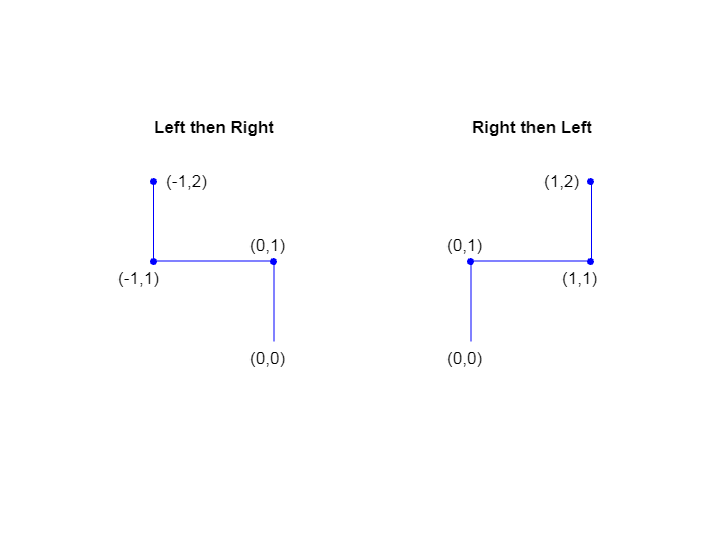

fig1()

**Square and diagonal matrices.    **If two matrices $A$ and $B$ are square matrices with the same dimensions $(A,B\in{\mathbb R}^{n\times n}
$) then the two products $\textrm{AB}$ and $\textrm{BA}$ are define (though they may or may not be equal).    A subset of ${\mathbb R}^{n\times n}$ known as the ***diagonal matrices*** plays an important role in linear algebra and provides some insight into the non-commutativity of matrix multiplication.    A diagonal matrix is a matrix for which its ***off-diagonal*** entries (entries having a row index unequal to it column index) are all zero.  Examples of diagonal matrices include

                    
$$\left[\matrix{1 & 0 & 0 \cr 0 & 2 & 0 \cr 0 & 0 & 3}\right],\qquad
\left[\matrix{1 & 0 & 0& 0& 0 \cr 0 & 2 & 0 &0&0\cr 0 & 0 & 3&0&0\cr 0 & 0 & 0 & \pi & 0\cr 0 & 0 & 0 & 0 &0}\right],\qquad
\left [\matrix{4}\right],\qquad
\left[\matrix{0&0\cr0&0}\right],\qquad
\left[\matrix{a & 0 & 0 &0\cr0 & b & 0 & 0 \cr 0 & 0 & c & 0 \cr 0 & 0 & 0 & d}\right].
$$


When a matrix $A$ is multiplied on the right by a compatible diagonal matrix, the result is to scale each column of the matrix $A$by the corresponding value from the diagonal of the diagonal matrix:

        (I.6.9)               $\left[\matrix{{\bf a}_1 & {\bf a}_2&\cdots&{\bf a}_n}\right]
\left[\matrix{\lambda_1&0&\cdots & 0 \cr 0 & \lambda_2 & \ddots& \vdots\cr
\vdots & \ddots& \ddots & \vdots \cr
0&\cdots & 0 & \lambda_n\cr
}\right]~=~
\left[\matrix{\lambda_1{\bf a}_1 & \lambda_2{\bf a}_2&\cdots&\lambda_n{\bf a}_n}\right]$.

Similarly, when a matrix $A$ is multiplied on the left by a compatible diagonal matrix, the result is to scale each row of $A$ by the corresponding value from the diagonal of the diagonal matrix.     

One diagonal matrix, the ***identity matrix***, plays an especially important role in matrix algebra.    The $n\times n$ identity matrix is a diagonal matrix having the value 1 for all its diagonal entries.   The identity matrix is denoted by $I$ (or possibly by $I_n
$ or $I_{n\times n}$ if there is any possible confusion about the dimensions.   For example, $I_1,~I_2,~I_3,~I_4,~I_5$:

                         
$$\left[\matrix{1}\right],\qquad
\left[\matrix{1&0\cr0&1}\right],\qquad
\left[\matrix{1&0&0\cr0&1&0\cr 0&0&1}\right],\qquad
\left[\matrix{1&0&0&0\cr0&1&0&0\cr 0&0&1&0\cr 0&0&0&1}\right],\qquad
\left[\matrix{1&0&0&0&0\cr0&1&0&0&0\cr 0&0&1&0&0\cr 0&0&0&1&0\cr0&0&0&0&1}\right].$$


When a compatible matrix $A$ is multiplied on the left (or right) by $I$ the result is $A$.   For this reason, $I$ is known as the ***multiplicative identity.***    Note that when multiplied by a compatible square matrix $A$, $\textrm{AI}=\textrm{IA}$; that is, the identity matrix commutes with all compatible square matrices.

**Matrix transpose.   **Beyond formation of linear combinations and matrix multiplication, the matrix transpose is a simple but vitally important operation on matrices.    The transpose of an $m\times n$ matrix $A$ (denoted $A^T$) is $m\times n$ matrix that simple converts each row to a column.   For example,

                 
$$\left[\matrix{1&2&3\cr 4 &5&6\cr 7&8&9}\right]^T~=~
\left[\matrix{1&4&7\cr2&5&8\cr 3&6&9}\right],\qquad
\left[\matrix{1&2\cr3&4\cr5&6\cr 7&8}\right]^T~=~
\left[\matrix{1&3&5&7\cr2&4&6&8}\right],\qquad
\left[\matrix{1&2&3&4}\right]^T~=~\left[\matrix{1\cr2\cr3\cr4}\right],\qquad \left[1\right]^T~=~\left[1\right]^T.$$


MATLAB distinguishes between the transpose and the conjugate transpose (discussed below).   However, for real matrices these two operations produce exactly the same result.   Hence, we use the MATLAB operator for the conjugate transpose, an apostrophe (') directly after the matrix, for real matrices without undue concern.

A=[1 2; 3 4; 5 6; 7 8]

A =      1     2
     3     4
     5     6
     7     8


A'

ans =      1     3     5     7
     2     4     6     8


Two simple observations:     (1)  The transpose of the transpose is the original matrix:   $\left(A^T\right)^T~=~A$.   (2)  If $B=A^T$then $B_{ij}=A_{ji}.$

The matrix transpose is intimately connected to the dot product:   If ${\bf x}~\text{and}~{\bf y}$ are vectors in ${\mathbb R}^n$ then,

        (I.6.10)                   ${\bf x}\cdot{\bf y}~=~{\bf x}^T{\bf y}~=~{\bf y}^T {\bf x}$.

The product ${\bf x}^T{\bf y}$ is sometimes also called the (Euclidean) ***inner product*** of ${\bf x}$ and ${\bf y}$.  The product with the transpose of the second factor ${\bf x}{\bf y}^T$, is in this context called the ***outer product ***of ${\bf x}$ and ${\bf y}$.  For example,

            ${\bf x}=\left[\matrix{1\cr2\cr3}\right]\quad\text{and}\quad
{\bf y}=\left[\matrix{2\cr 0 \cr -1}\right]\qquad\Rightarrow\qquad
{\bf x}\cdot{\bf y}~=~{\bf x}^T{\bf y}=-1\quad\text{and}\quad
{\bf x}\otimes{\bf y}~=~{\bf x}{\bf y}^T=\left[\matrix{2 & 0 & -1\cr 4&0&-2\cr6&0&-3}\right]$.

In the follow up problems representations of the matrix-matrix product in terms of inner products and outer products are derived.   These representations come to play an important role in interpreting and using results towards the end of the course.

**Symmetric and antisymmetric matrices.**    A (real) matrix $A$ is said to be ***symmetric*** if it equals its transpose $A^T=A$.   For example,

                        
$$\left[\matrix{
1 & 2 & 3 & 4\cr
2  &5 & 6 & 7 \cr
3  &6& 8 & 9 \cr
4 & 7& 9&10
}
\right]^T~=~\left[\matrix{
1 & 2 & 3 & 4\cr
2  &5 & 6 & 7 \cr
3  &6& 8 & 9 \cr
4 & 7& 9&10
}
\right]$$


Hence, $A$ is symmetric if $A_{ij}=A_{ji}~\text{for}~1\le i,j\le n.$   Visually, the matrix equals its reflection through the main diagonal.    

A (real) matrix $A$ is said to be ***antisymmetric*** if it equals the negative of its transpose $A^T=-A$.   For example,

                        $\left[\matrix{
0 & 2 & 3 & 4\cr
-2  &0 & 6 & 7 \cr
-3  &-6& 0 & 9 \cr
-4 & -7& -9&0
}
\right]^T~=~-\left[\matrix{
0 & 2 & 3 & 4\cr
-2  &0 & 6 & 7 \cr
-3  &-6& 0 & 9 \cr
-4 & -7& -9&0
}\right]$.

Alternatively, $A$ is antisymmetric if $A_{ij}=-A_{ji}~\text{for}~1\le i,j\le n.$   Visually, reflection through the main diagonal flips the sign of all the entries.   Note that the main diagonal of an antisymmetric matrix consists only of zeros since $A_{ii}=-A_{ii}$ .

**The transpose of a product.  **An important pattern (worthy of rote memorization) is

        "The transpose of a product is the product of the transposes taken in the opposite order."

In symbols,

        (I.6.11)                        $(AB)^T~=~B^T A^T$.

The pattern extends to products of multiple factors:  $(A_1 A_2\cdots A_p)^T~=~A_p^T\cdots  A_2^TA_1^T$.

**The Gram matrix.   **The matrix transpose is used to associate to every real matrix $A$ a matrix $A^TA$ known as the ***Gram matrix*** of $A$.   For example,

A=[1 1 1; 1 2 4; 1 3 9; 1 4 16; 1 5 25; 1 6 36]    % a matrix

A =      1     1     1
     1     2     4
     1     3     9
     1     4    16
     1     5    25
     1     6    36


A'*A     % the Gram matrix of A

ans =            6          21          91
          21          91         441
          91         441        2275


In much analysis and in many applications the Gram matrix has a central role.     Perhaps, the most basic property of the Gram matrix is that the entry in the $i^\text{th}$ row and $j^\text{th}$ column is the dot product of the $i^\text{th}$ and $j^\text{th}$ columns of $A$.    

                    
$$A^TA~=~\left[\matrix{ {\bf a}_1 &{\bf a}_2 &\cdots&{\bf a}_n}\right]^T\left[\matrix{ {\bf a}_1 &{\bf a}_2 &\cdots&{\bf a}_n}\right]~=~
\left[\matrix{
{\bf a}_1\cdot{\bf a}_1 & {\bf a}_1\cdot{\bf a}_2 &\cdots &{\bf a}_1\cdot{\bf a}_n \cr
{\bf a}_2\cdot{\bf a}_1 & {\bf a}_2\cdot{\bf a}_2 &\cdots &{\bf a}_2\cdot{\bf a}_n \cr
\vdots & \vdots & \ddots & \vdots \cr
{\bf a}_n\cdot{\bf a}_1 & {\bf a}_n\cdot{\bf a}_2 &\cdots &{\bf a}_n\cdot{\bf a}_n \cr
}\right]$$


Note that the Gram matrix is square and symmetric.

**Hermitian transpose.**   It turns out that the definition of transpose given above for real matrices above has a major defect for when applied directly to complex matrices: the loss of non-negativity.     The dot product has the property that for ${\bf x}\in{\mathbb R}^n$ 

        (I.6.12a)                   ${\bf x}\cdot{\bf x}~=~x_1^2+x_2^2+\cdots+x_n^2~\ge~0.$

However, if ${\bf x}\in {\mathbb C}^n$ and the dot product is defined as ${\bf x}^T{\bf x}$ this property is lost.   For example,

                    
$${\bf x}=\left[\matrix{1\cr 2 \cr 3 i}\right]\qquad\Rightarrow\qquad
{\bf x}^T{\bf x}~=~1^2+2^2+(3i)^2=1+4-9=~-4.$$


For complex numbers the sum of squares may be negative.   To remedy this situation, we make use of the Hermitian transpose (aka the conjugate transpose) which both exchanges rows and columns and replaces each entry by its complex conjugate (denoted here with an asterisk (*)):   $A^H=(A^T)^*$.    For example,

                
$$\left[\matrix{1 & 2+i & 3-i\cr 4 & i & 2-i\cr -1 & 2 & 7i}\right]^H~=~
\left[\matrix{1 & 4 & -1\cr 2+i & i & 2 \cr 3-i & 2-i & 7i}\right]^*~=~
\left[\matrix{1 & 4 & -1\cr 2-i & -i & 2 \cr 3+i & 2+i & -7i}\right].$$


For complex vectors ${\bf x}\in{\mathbb C}^n$using the Hermitian transpose to define the dot product recovers the non-negativity property since the product of a complex number with its conjugate is non-negative.

        (I.6.12b)        ${\bf x}\cdot{\bf x}~=~{\bf x}^H{\bf x}~=~\left[\matrix{x_1^* & x_2^* &\cdots & x_n^*}\right]\left[\matrix{x_1\cr x_2\cr\vdots \cr x_n}\right]~=~ x_1^*x_1~+~x_2^*x_2~+~\cdots~+~x_n^* x_n ~\ge~0.$

Hence, the notion of the norm (or length) of a vector extends to complex vectors in a way that assures the norm is always a non-negative real number:

         (I.6.12c)               $||{\bf x}||~=~\sqrt{{\bf x}^H{\bf x}}$.

For both theoretical and applied reasons, the Hermitian transpose is the most appropriate extension of the concept of transpose to complex matrices.    Hermitian symmetric matrices, $A^H=A$, play a fundamental role in the physical sciences most notably in quantum mechanics.

The Hermitian transpose is denoted by an apostrophe (`')` in MATLAB.

format rat           % print numbers as rational numbers (or integers)
[1 2+i 3-i; 4 i 2-i; -1 2 7*i]'

ans =        1        +    0i             4        +    0i            -1        +    0i      
       2        -    1i             0        -    1i             2        +    0i      
       3        +    1i             2        +    1i             0        -    7i      


**Some new algebra.   **Matrix algebra shares many features of real number algebra, but a few matters require some attention.   (1) Due to the requirements on the dimensions of matrices for operations to be defined, it is relatively easy for reasonable looking expressions, such as ${\bf x}+{\bf y}$ or $A{\bf x}$ to be undefined.   Consider

                                $\left[\matrix{1\cr2\cr3}\right]~+~\left[\matrix{0\cr0}\right]\qquad\text{and}\qquad
\left[\matrix{1 & 2 \cr 3 & 4 \cr 5 & 6}\right]
\left[\matrix{1\cr2\cr3}\right]$.

(2)   Matrix algebra satisfies distributive and associative laws analogous to real number algebra but the non-commutativity of matrix multiplication must be kept in mind.    For example, the standard algebraic identity $(a+b)(a-b)=a^2-b^2$ does not extend cleanly to matrix algebra:

                $(A+B)(A-B)~=~A(A-B)~+~B(A-B)~=~A^2-AB+BA-B^2$ .

Further simplification using, $-AB+BA=0$, is generally invalid due to non-commutativity.  (3)  In real number algebra, a product equal to zero implies that one of the factors equals zero.   The extension of this result to matrix algebra is not obvious as the product of two matrices containing no zeros may be a zero matrix; for example,

                            $\left[\matrix{1 & -1\cr -1 & 1 }\right] \left[\matrix{2&3\cr2&3}\right]~=~\left[\matrix{0&0\cr 0&0}\right]$.

### **Follow-up (aka homework)**

**Problem I.6.1:**   Find coefficients showing that $\left[\matrix{1&0&-1\cr 8&7&6}\right]$is a linear combination of $\left[\matrix{2&6&10\cr 4&8&12}\right]$and $\left[\matrix{3&6&9\cr 12&15&18}\right]$.

**Problem I.6.2:**   Is $\left[\matrix{0&0\cr 0&0}\right]$a linear combination of $\left[\matrix{1&3\cr 8&2\cr}\right]$and $\left[\matrix{1&1\cr -1&4\cr}\right]$?

**Problem I.6.3:**   Is $\left[\matrix{1&1\cr 1&1}\right]$a linear combination of $\left[\matrix{1&3\cr 8&2\cr}\right]$and $\left[\matrix{1&1\cr -1&4\cr}\right]$?

**Problem I.6.4:   **For how many sets of coefficients can $\left[\matrix{7&-7\cr-7&7}\right]$be written as a linear combination of $\left[\matrix{1&-1\cr-1&1}\right]$ and $\left[\matrix{-1&1\cr1&-1}\right]$?

**Problem I.6.5:   **Plot all the linear combinations $\alpha \left[\matrix{1\cr1}\right]~+~
\beta \left[\matrix{1\cr-1}\right]$ where $0\le\alpha\le3$ and $0\le\beta\le4$.

**Problem I.6.6:   **Plot all the linear combinations $\alpha \left[\matrix{1\cr1}\right]~+~
\beta \left[\matrix{1\cr-1}\right]$ where $0\le\alpha\le3$ and $0\le\beta\le4$ and the coefficients are integers.

**Problem I.6.7:   **Plot all the linear combinations $\alpha \left[\matrix{1\cr1}\right]~+~
\beta \left[\matrix{1\cr-1}\right]$ where $\alpha+\beta=1$.

**Problem I.6.8:   **Plot all the linear combinations $\alpha \left[\matrix{1\cr1}\right]~+~
\beta \left[\matrix{1\cr-1}\right]$ where $\alpha+\beta\le 1$.

**Problem I.6.9:**   Compute all defined products of pairs of matrices from the following four matrices:

            
$$A=\left[\matrix{1 & 2 & 3 & 4\cr 1&0&1&0\cr}\right],\qquad
B=\left[\matrix{1 & 0\cr 0 & 1 \cr 1 & 1\cr 1&-1}\right],\qquad
C=\left[\matrix{1\cr 0 \cr -1 \cr 0}\right]\quad\text{and}\quad
D=\left[\matrix{1 & 2 & 3 & 4 & 5}\right].$$


**Problem I.6.10:  **Suppose that $A$is a $p\times m$ matrix with columns ${\bf a}_1,\dots,{\bf a}_m$ and $B$ is a$p\times n$ matrix with columns ${\bf b}_1,\dots,{\bf b}_n$.  Verify

$A^TB=\left[\matrix{
{\bf a}_1\cdot{\bf b}_1&{\bf a}_1\cdot{\bf b}_2&\cdots&{\bf a}_1\cdot{\bf b}_n\cr
{\bf a}_2\cdot{\bf b}_1&{\bf a}_2\cdot{\bf b}_2&\cdots&{\bf a}_2\cdot{\bf b}_n\cr
\vdots & \vdots &&\vdots\cr
{\bf a}_m\cdot{\bf b}_1&{\bf a}_m\cdot{\bf b}_2&\cdots&{\bf a}_m\cdot{\bf b}_n\cr
}\right]$.

Hence, the entries of $A^TB$ are the dot products of the columns of $A$ with the columns of $B$.

**Problem I.6.11:   **Suppose that $A$is a $m\times p$ matrix with columns ${\bf a}_1,\dots,{\bf a}_p$ and $B$ is a $n\times p$ matrix with columns ${\bf b}_1,\dots,{\bf b}_p$.  Verify

$AB^T~=~{\bf a}_1\otimes{\bf b}_1~+~
{\bf a}_2\otimes{\bf b}_2~+~\cdots~+~ {\bf a}_p\otimes{\bf b}_p$ .

Hence, the product $AB^T$is the sum of the outer products of the corresponding columns of $A$and $B$.

**Problem I.6.12:**  Rewrite the linear system    $\left\{\matrix{
3x&+&7y&-&3z&=&9 \cr
&&y&+&2z&=&2 \cr
x&-&y&-&5z&=&1 \cr}\right.$      in the form $A{\bf x}={\bf b}$.

**Problem I.6.13:**   Let $U\subset {\mathbb R}^2$ be the unit square in the plane

                $U=\{(x,y)~:~0\le x\le 1,~0\le y \le 1\}$.

Let $T_A:{\mathbb R}^2\to{\mathbb R}^2$ be defined by $T_A({\bf x})=A{\bf x}$ where $A=\left[\matrix{1&1\cr 1&-1}\right]$.   Plot $T_A(U)$, the image of $U$ under $T_A$, defined by

                    $T_A(U)=\{T_A({\bf x})=A{\bf x}~:~{\bf x}\in U\}$.

**Problem I.6.14:**   Under what conditions on the dimensions of $A$ and $B$ are the two products $\textrm{AB}$ and $\textrm{BA}$ both defined?

**Problem I.6.15:**   Under what conditions on the dimensions of $A$ and $B$ do the two products $\textrm{AB}$ and $\textrm{BA}$ have the same dimensions?

**Problem I.6.16:   **Consider a delivery drone that uses a unit vector ${\bf d}$ to represent its current direction of travel.   Suppose the drone periodically receives one of the following instructions to change direction:   "turn left", "turn right", "go straight".     Verify that the direction of travel may be updated to ${\bf d}'$using matrix-vector multiplication as follows:

            "turn left"         ${\bf d}'~=~L{\bf d}$    where    $L~=~\left[\matrix{0 & -1\cr1 & 0 }\right]$,

            "turn right"       ${\bf d}'~=~R{\bf d}$    where    $R~=~\left[\matrix{0 & 1\cr-1 & 0 }\right]$,

            "go straight"     ${\bf d}'~=~I{\bf d}$    where    $I~=~\left[\matrix{1 & 0\cr 0 & 1 }\right]$.

Verify that the three matrices $L,~R~\text{and}~I$ commute with one another.

**Problem I.6.17:**   Suppose that a delivery drone, which travels at a constant speed, receives turning instruction periodically in such a way that its location ${\bf x}_n$ and direction of travel ${\bf d}_n$ at time $n$ satisfies $\left\{ \matrix{ {\bf x}_{n+1}&=&{\bf x}_n&+&{\bf d}_n\cr
{\bf d}_{n+1}&=&C_n {\bf d}_n 
}
\right.$  where $C_n$ is one of $L$, $R$ or $I$ defined in the previous problem.    Verify that 

$\left[\matrix{{\bf x}_{n+1}\cr {\bf d}_{n+1}}\right]~=~A_n \left[\matrix{{\bf x}_n\cr {\bf d}_{n}}\right]$ where $A_n~=~\left[\matrix{I&I\cr Z&C_n}\right]$ and $Z=\left[\matrix{0&0\cr0&0}\right]$is the $2\times 2$ zero matrix.   Hence, $\left[\matrix{{\bf x}_n\cr {\bf d}_n}\right]~=~A_{n-1}A_{n-2}\cdots A_2 A_1A_0\left[\matrix{{\bf x}_0\cr{\bf d}_0}\right]$.

Show

                        $\left[\matrix{I& I\cr Z & L}\right] 
\left[\matrix{I& I\cr Z & R}\right] 
\ne
\left[\matrix{I& I\cr Z & R}\right] 
\left[\matrix{I& I\cr Z & L}\right] 
$.

**Problem I.6.18:**  Let $T:{\mathbb R}^2\to{\mathbb R}^2$ be defined by $T({\bf x})=\left[\matrix{2 &1\cr1&2}\right]{\bf x}$.  The unit square $U$ in the domain ${\mathbb R}^2$ is defined by

                    $U=\left\{~ \left[\matrix{x_1\cr x_2}\right]~:~ 0\le x_1\le1\quad\text{and}\quad 0\le x_2\le1\right\}$.

The image of $U$ under $T$ is written $T\left(U\right)$ and defined by

                    $T(U)~=~\{T({\bf x})\quad:\quad {\bf x}\in U\}$.

Plot (using MATLAB if feasible) $U$and $T\left(U\right)$ on separate axes.

**Problem I.6.19:   **Compute and simplify the $p^\text{th}$ power of the general $n\times n$ matrix:  $\left[\matrix{\lambda_1&0&\cdots & 0 \cr 0 & \lambda_2 & \ddots& \vdots\cr
\vdots & \ddots& \ddots & \vdots \cr
0&\cdots & 0 & \lambda_n\cr
}\right]^p$.   State in words the rule for computing a power of a diagonal matrix.   Does this rule work for fractional or negative powers?

**Problem I.6.20:   **Given an example of two $2\times 2$ diagonal matrices neither of which is a zero matrix but the product of the two matrices is a zero matrix.

**Problem I.6.21:   **For each pair of vectors from the set

                
$$\left\{
\left[\matrix{1\cr 2 \cr 3}\right],~
\left[\matrix{3\cr 2 \cr 1}\right],~
\left[\matrix{1\cr 2}\right],~
\left[\matrix{-1\cr 1}\right]\right\}$$


compute all defined inner and outer products.

**Problem I.6.22**:   For each pair of vectors from the set

                
$$\left\{
\left[\matrix{1+i\cr 2-i \cr 3+2i}\right],~
\left[\matrix{1+i\cr 1-i}\right]\right\}$$


compute all defined inner and outer products.

**Problem I.6.23: ** Show $(AB)^T=B^T A^T$.

**Problem I.6.24:  **Why is the Gram matrix symmetric?

**Problem I.6.25:  **If $A\in{\mathbb C}^{n\times n}$ then the symmetric part of $A$ is the matrix $\frac12(A+A^H)$ and the antisymmetric part of $A$ is the matrix $\frac12(A-A^H)$.   Compute the symmetric and antisymmetric parts of the matrix $A=\left[\matrix{1&5&0\cr -1&4&1\cr 6 & 9 & 6}\right]$.    Verify for all square matrices that the symmetric part is a symmetric matrix and that the antisymmetric part is an antisymmetric matrix.   Verify for all square matrices that the sum of the symmetric part and the antisymmetric part is the matrix.

**Problem I.6.26:**   The geometric interpretation of the dot product in the formula present in the formula ${\bf x}\cdot{\bf y}=||{\bf x}|| ||{\bf y}|| \cos\theta$ makes plausible the Cauchy-Schwarz inequality:

                        $|{\bf x}\cdot{\bf y}|~\le~||{\bf x}||\, || {\bf y}||$.

However, when the vectors have complex components making the dot product potentially a complex number, it is not obvious that this inequality will be valid for complex vectors.    In this problem, the Cauchy-Schwarz inequality is derived for both real and complex vectors:    

- Note that $||{\bf x}+\alpha{\bf y}||^2\ge0$ for all values of $\alpha$.

- In the case ${\bf y}\ne{\bf 0}$ find the unique real value of $\alpha$ minimizing $||{\bf x}+\alpha{\bf y}||^2$.

- Show that substituting this minimizing value of $\alpha$ into the inequality $||{\bf x}+\alpha{\bf y}||^2\ge0$ implies the Cauchy-Schwarz inequality.

**Problem I.6.27:**   Assuming each individual sum and product are defined, verify or disprove each of the following identities:

        (a)    $A(B+C)=AB+AC
$

        (b)    $(B+C)A=BA+CA$

        (c)     $(AB)C=A(BC)$ 

        (d)    $(AB)C=C(AB)$

**Problem I.6.28:  **For two general $n\times n$ matrices $A$ and $B$, determine which of the following equations are always true.

        (a)    $(A+B)^2 = A^2+2AB+B^2$

        (b)    $(A-B)^2=A^2-AB+BA+B^2$

        (c)     $(A+B)^2-(A-B)^2=2(AB+BA)$

        (d)    $I-A^{n+1}=(I-A)(I+A+A^2+\cdots+A^n)\qquad n=1,2,\dots$

**Common Quiz 3****: Matrix Operations**

Common Quiz 3 covers performing matrix operations including addition, multiplication and taking the transpose.

function fig1()
subplot(1,2,1)
hold on
axis([-1.5,0.5,-0.5,2.5])
axis square
axis off
title('Left then Right')
plot([0 0],[0 1],'b')
plot(0,1,'.b','MarkerSize',12)
text(-0.2,1.2,'(0,1)')
text(-0.2,-0.2,'(0,0)')
plot([0 -1],[1 1],'b')
plot(-1,1,'.b','MarkerSize',12)
text(-1.3,0.8,'(-1,1)')
plot([-1 -1],[1 2],'b')
plot(-1,2,'.b','MarkerSize',12)
text(-0.9,2,'(-1,2)')
subplot(1,2,2)
hold on
axis([-0.5,1.5,-0.5,2.5])
axis square
axis off
title('Right then Left')
plot([0 0],[0 1],'b')
plot(0,1,'.b','MarkerSize',12)
text(-0.2,1.2,'(0,1)')
text(-0.2,-0.2,'(0,0)')
plot([0 1],[1 1],'b')
plot(1,1,'.b','MarkerSize',12)
text(0.75,0.8,'(1,1)')
plot([1 1],[1 2],'b')
plot(1,2,'.b','MarkerSize',12)
text(0.6,2,'(1,2)')
end